# Correlation integral dependence on aromatic, sidechain, and backbone parameters

Plot average and standard deviation of correlation integral for all different sets of parameters.

## Read in Data

fileLocation = '/home/rachael/cluster/scratch/ramansbach/coarsegraining/hoomd/patchy/analyze/';
AAnames = {'250','500','750'};
SCnames = {'02','2','4','6','10'};
Rnames = {'025','050','075','100','125','150','200'};
%track different types of parameters/clustering types
colors = {};
c1 = [0 0.4470 0.7410];
c2 = [0.8500 0.3250 0.0980];
c3 = [0.9290 0.6940 0.1250];
c4 = [0.4940 0.1840 0.5560];
c5 = [0.4660 0.6740 0.1880];
c6 =  [0.3010 0.7450 0.9330];
c7 = [0.6350 0.0780 0.1840];
c8 = [0,0,0];
cs = {c1,c2,c3,c4,c5,c6,c7,c8};

fbase = 'mols10000_';
paramMatrix = zeros(length(AAnames),3);
contactMatrix = zeros(length(AAnames),7);
opticalMatrix = zeros(length(AAnames),7);
alignedMatrix = zeros(length(AAnames),7);
dataCell = {};
tframes = 10:100:710;

for i = 1:length(AAnames)
    for sc = 1:length(SCnames)
        for sig = 1:length(Rnames)
    foldname = [fileLocation AAnames{i} '-' SCnames{sc} '-' Rnames{sig} '/'];
    
    fname = [foldname fbase AAnames{i} '-' SCnames{sc} '-' Rnames{sig} '_short_run-corrcalc'];
    
        
    try
       dataMatrix = [];
       for t = tframes
           
           data = importdata([fname num2str(t) '.dat']);
           x = data(:,1);
           dataMatrix = [dataMatrix data(:,2)];
       end
       dataMatrix = [x dataMatrix];
    catch
       dataMatrix = []; 
    end
    dataCell{i}{sc}{sig} = dataMatrix;
        end
    end
end


Okay two things:

First, there's an obvious region break according to the variance, and we can do a local min search where we fit three lines to the variance to pick the exact breaks.

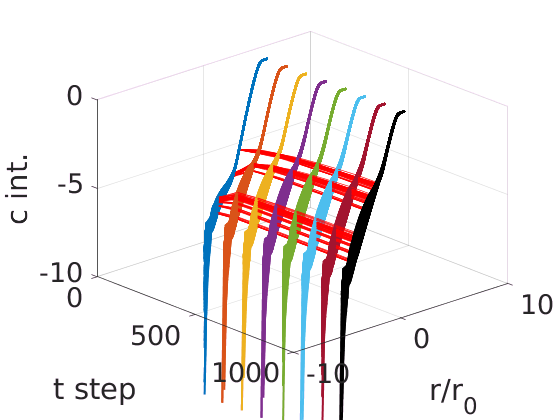

figure()
hold on
set(gca,'fontsize',20)
yMeans = [];
yind = 1;
for a = 1:length(AAnames)
    for sc = 1:length(SCnames)
        for sig = 1:length(Rnames)
            dataMatrix = dataCell{a}{sc}{sig};
            if ~isempty(dataMatrix)
                x = dataMatrix(:,1);
                y = dataMatrix(:,end);%just look at the final frame 
                yMeans(:,yind) = y;
                
                yind = yind + 1;
                s = std(dataMatrix(:,2:end),0,2);
                %errorbar(x,y,s,'linewidth',2)
                for t = 1:length(tframes)
                    plot3(tframes(t)*ones(size(x)),log(x),log(dataMatrix(:,t+1)),'linewidth',1.5,'color',cs{t})
                end
                plot3(tframes,log(x(83))*ones(size(tframes)),log(dataMatrix(83,2:end)),'r')
                plot3(tframes,log(x(150))*ones(size(tframes)),log(dataMatrix(150,2:end)),'r')
                plot3(tframes,log(x(20))*ones(size(tframes)),log(dataMatrix(20,2:end)),'r')
                grid on
                view(47.5,30)
                zlabel('c int.')
                ylabel('r/r_0')
                xlabel('t step')
                
            end
        end
    end
end
zlim([-10 0])

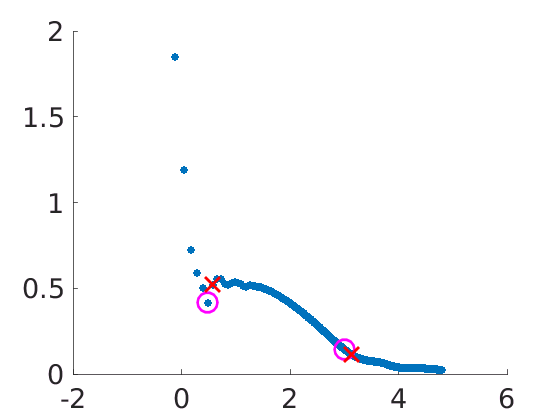

xsig = log(x(~isnan(std(log(yMeans),0,2))));
sigma = std(log(yMeans),0,2);
sigma = sigma(~isnan(sigma));
imax = find(abs(xsig-4.8)==min(abs(xsig-4.8)));
xsig = xsig(1:imax);
sigma = sigma(1:imax);
figure()
hold on
plot(xsig,sigma,'.','markersize',20)
set(gca,'fontsize',20)
checkNo = 20; %check 20 points to either side
iguess1 = find(abs(xsig-0.4806)==min(abs(xsig-0.4806)));
iguess2 = find(abs(xsig-3)==min(abs(xsig-3)));
lf = fittype('a*x+b','independent','x');
minerr = Inf;
warning('off','curvefit:fit:noStartPoint')
for i1 = max(iguess1-checkNo,2):min(iguess1+checkNo,length(sigma)-2)
    for i2 = max(iguess2-checkNo,2):min(iguess2+checkNo,length(sigma)-2)
       [P1,gP1] = fit(xsig(1:i1),sigma(1:i1),lf);
       [P2,gP2] = fit(xsig(i1:i2),sigma(i1:i2),lf);  
       [P3,gP3] = fit(xsig(i2:end),sigma(i2:end),lf);
       %compute total RMSE
       %RMSET = ((j-1)/(length(vals)-1))*RMSE1 + ((length(vals)-j)/(length(vals)-1))*RMSE2,
        RMSET = ((i1-1)/(length(sigma)-1))*gP1.rmse + ((i2-i1)/(length(sigma)-1))*gP2.rmse + ((length(sigma)-i2)/(length(sigma)-1))*gP3.rmse;
        if RMSET < minerr
           minerr = RMSET;
           split1 = i1;
           split2 = i2;
        end
    end
end
plot([xsig(iguess1) xsig(iguess2)],[sigma(iguess1) sigma(iguess2)],'mo','linewidth',2,'markersize',15)
plot([xsig(split1) xsig(split2)],[sigma(split1) sigma(split2)],'rx','markersize',15,'linewidth',2)

x1 = xsig(split1)

x1 = 0.5676

x2 = xsig(split2)

x2 = 3.1389

Check a linear fit for the collapsed region.

## Plot Data

For each non empty piece of data, get the mean and the standard deviation and plot it on the figure.

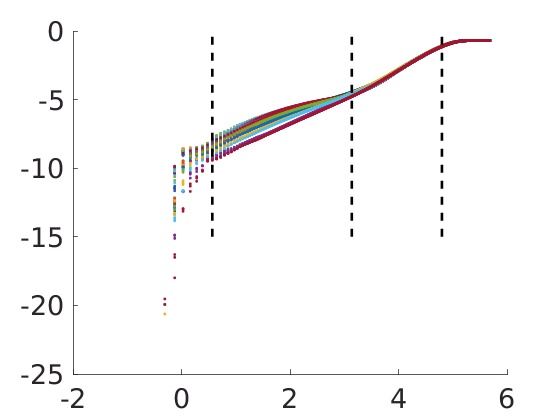

figure()
set(gca,'fontsize',20)
hold on;
yMeans = [];
yind = 1;

for a = 1:length(AAnames)
    for sc = 1:length(SCnames)
        for sig = 1:length(Rnames)
            dataMatrix = dataCell{a}{sc}{sig};
            if ~isempty(dataMatrix)
                x = dataMatrix(:,1);
                y = mean(dataMatrix(:,2:end),2);
                yMeans(:,yind) = y;
                
                yind = yind + 1;
                s = std(dataMatrix(:,2:end),0,2);
                %errorbar(x,y,s,'linewidth',2)
                plot(log(x),log(y),'.','linewidth',1.5)
                %xlim([log(1.5) log(73.3)])
                %xlim([0 4.5])
                
                %ylim([-15 0])
            end
        end
    end
end
plot(4.8*ones(size(-15:0)),-15:0,'--k','linewidth',2)
plot(x2*ones(size(-15:0)),-15:0,'--k','linewidth',2)
plot(x1*ones(size(-15:0)),-15:0,'--k','linewidth',2)

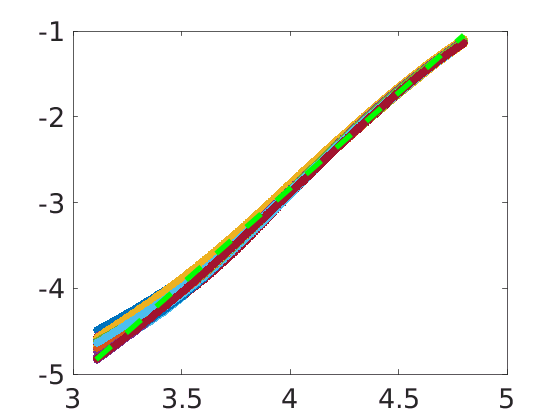

figure()
imaxx = find(abs(log(x)-4.8)==min(abs(log(x)-4.8)));
lf = fittype('a*x+b','independent','x');
plot(log(x(split2:imaxx)),log(yMeans(split2:imaxx,:)),'.','markersize',20)
set(gca,'fontsize',20)
[P1,gP1] = fit(log(x(split2:imaxx)),mean(log(yMeans(split2:imaxx,:)),2),lf);
hold on
plot(log(x(split2:imaxx)),P1(log(x(split2:imaxx))),'g--','linewidth',4)

cia = confint(P1);
cia = cia(:,1);
fprintf('Dimension is %f (%f,%f)',P1.a,cia(1),cia(2));

Dimension is 2.232460 (2.225470,2.239450)

Second, it's unclear as to whether a single linear fit or two is better for that central region, so use AIC to determine that for each run.

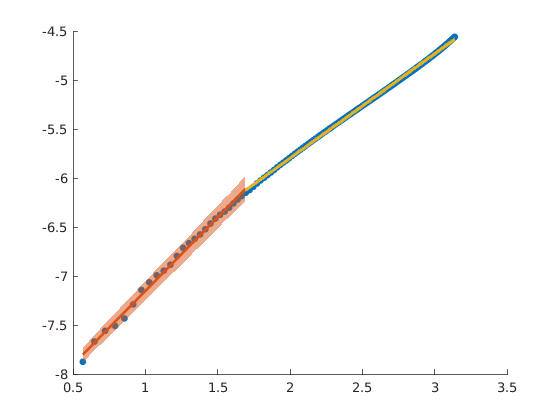

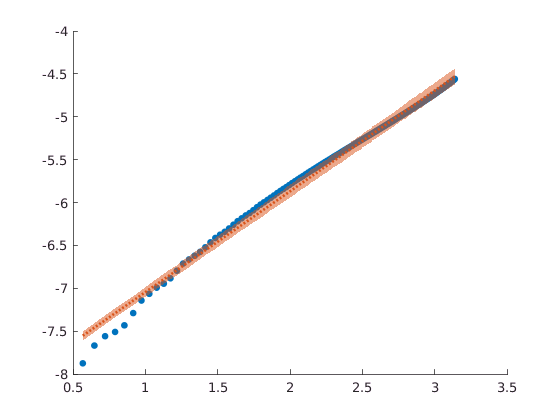

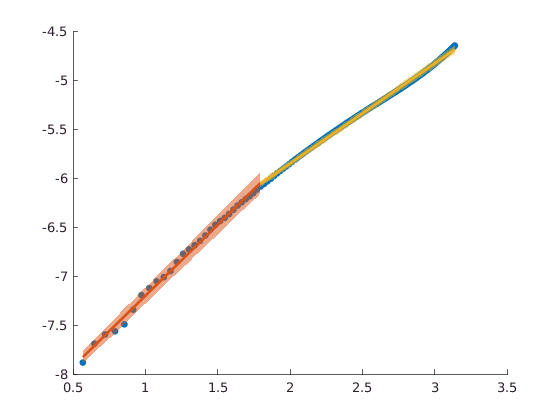

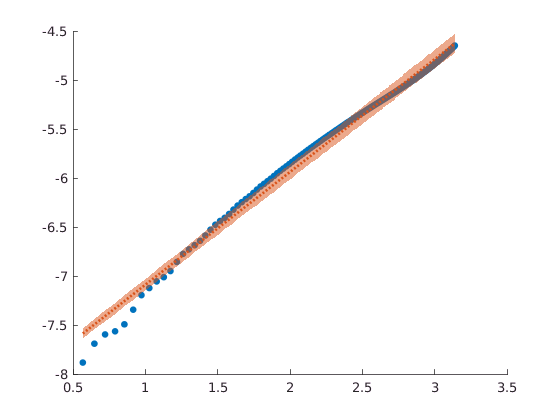

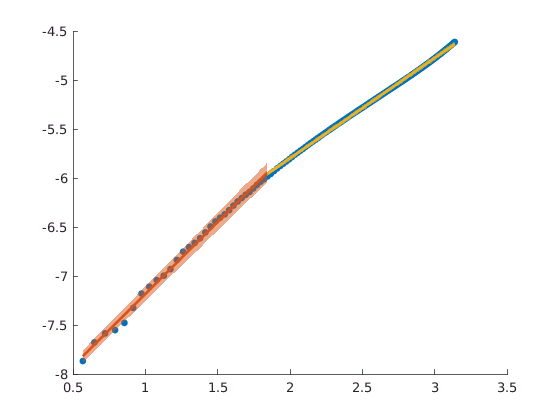

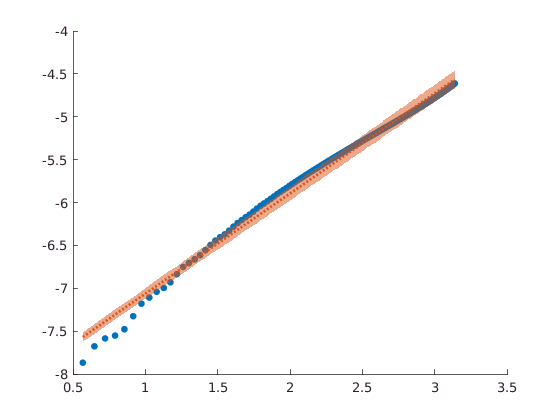

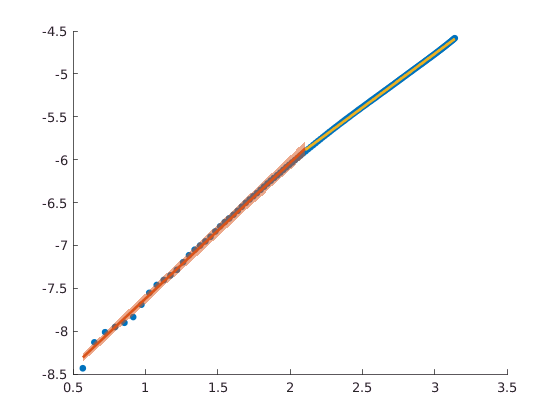

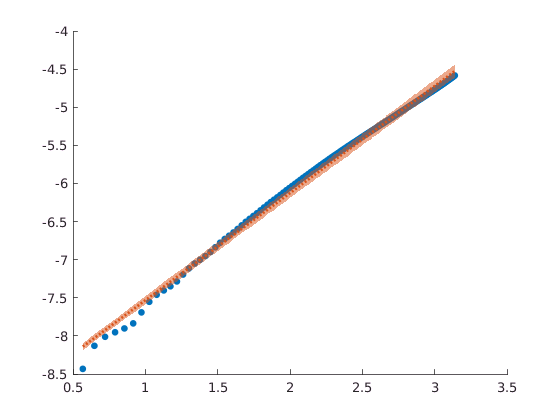

addpath('/home/rachael/Analysis_and_run_code/stats_analysis/');
figure()
dims = [];
for a = 1:length(AAnames)
    for sc = 1:length(SCnames)
        for sig = 1:length(Rnames)
            dataMatrix = dataCell{a}{sc}{sig};
            if ~isempty(dataMatrix)
                x = log(dataMatrix(:,1));
                y = log(mean(dataMatrix(:,2:end),2));
                
                s = std(dataMatrix(:,2:end),0,2);
                imin = find(abs(x-x1)==min(abs(x-x1)));
                imax = find(abs(x-x2)==min(abs(x-x2)));
                [l1,l2,splt,lsing,aic1,aic2] = Lmethod(x(imin:imax),y(imin:imax),[],0,0);
                AA = str2double(AAnames{a})/100;
                if strcmp(SCnames{sc},'02')
                   SC = 0.2; 
                else
                   SC = str2double(SCnames{sc}); 
                end
                if strcmp(Rnames{sig},'001')
                    sig = 0.01;
                else
                    sig = str2double(Rnames{sig});
                end
                if aic1 < aic2
                   d1 = lsing.a;
                   d2 = lsing.a;
                   xsplit = 0;
                else
                    d1 = l1.a;
                    d2 = l2.a;
                    xsplit = x(splt);
                end
                dimvec = [AA SC sig d1 d2 xsplit];
                dims = [dims;dimvec];
            end
        end
    end
end

## Now let's investigate these dimensions as a function of our parameter space

**Region 1**

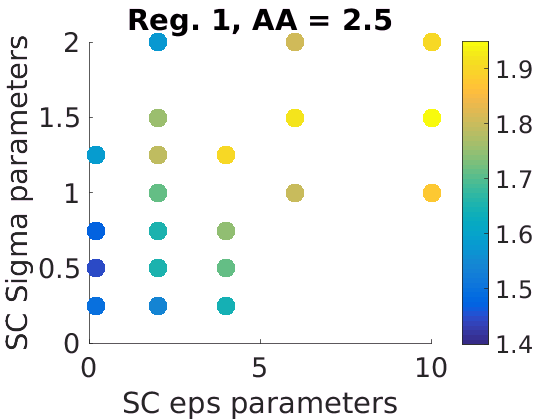

saveloc = '/home/rachael/coarsegraining/Data/patchy';
addpath('/home/rachael/Analysis_and_run_code/lab_notebook/CG_patchy');
addpath('/home/rachael/Analysis_and_run_code/lab_notebook/CG_patchy/helper_fcns');
figure()
hold on

%dims(:,3) = dims(:,3)/100;
i02 = find((dims(:,1)==2.5) & (dims(:,6) ~=0));
i01 = find((dims(:,1)==2.5) & (dims(:,6) ==0));
scatter(dims(i01,2),dims(i01,3),200,dims(i01,4))
scatter(dims(i02,2),dims(i02,3),200,dims(i02,4),'filled')
colorbar
caxis([1.4 1.95])
set(gca,'fontsize',20)
xlabel('SC eps parameters')
ylabel('SC Sigma parameters')
title('Reg. 1, AA = 2.5')
savefig([saveloc '/dimr1A250'])
saveas(gcf,[saveloc '/dimr1A250'],'pdf')

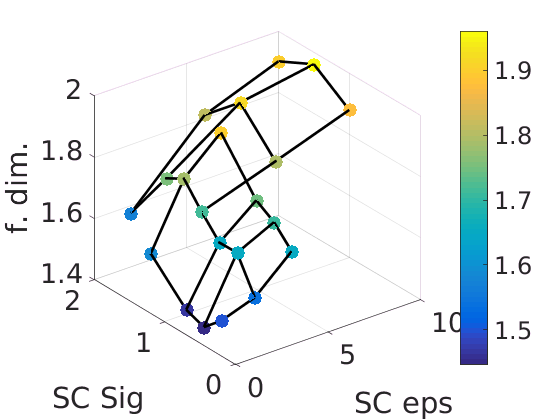


f = figure();
hold on
f = errorMesh(dims(i02,2),dims(i02,3),dims(i02,4),0.0*ones(size(dims(i02,2))),[0 0 0],f);
figure(f);
colorbar
set(gca,'fontsize',20);
xlabel('SC eps')
ylabel('SC Sig')
zlabel('f. dim.')
savefig([saveloc '/dimr1A2503D'])
saveas(gcf,[saveloc '/dimr1A2503D'],'pdf')

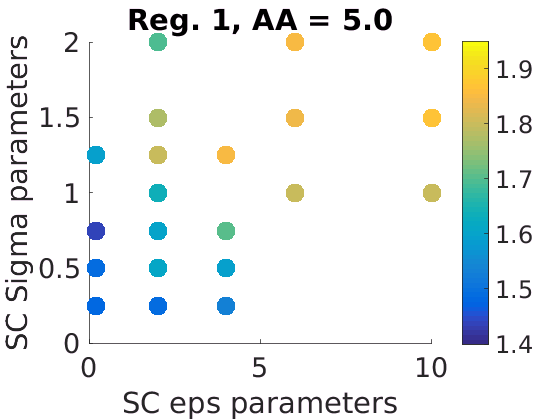


figure()
hold on

i02 = find((dims(:,1)==5) & (dims(:,6) ~=0));
i01 = find((dims(:,1)==5) & (dims(:,6) ==0));
scatter(dims(i01,2),dims(i01,3),200,dims(i01,4))
scatter(dims(i02,2),dims(i02,3),200,dims(i02,4),'filled')
colorbar
set(gca,'fontsize',20)
xlabel('SC eps parameters')
ylabel('SC Sigma parameters')
title('Reg. 1, AA = 5.0')
caxis([1.4 1.95])
savefig([saveloc '/dimr1A500'])
saveas(gcf,[saveloc '/dimr1A500'],'pdf')

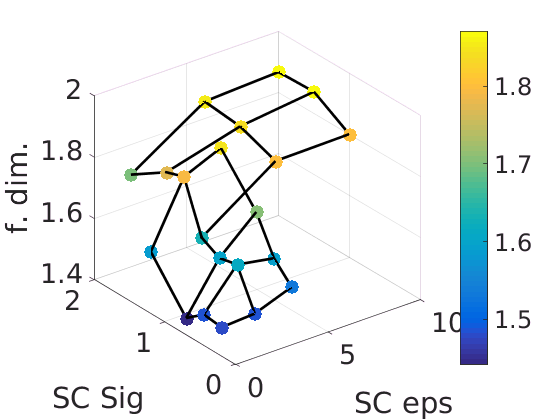


f = figure();
hold on

f = errorMesh(dims(i02,2),dims(i02,3),dims(i02,4),0.0*ones(size(dims(i02,2))),[0 0 0],f);
figure(f);
colorbar
set(gca,'fontsize',20);
xlabel('SC eps')
ylabel('SC Sig')
zlabel('f. dim.')
savefig([saveloc '/dimr1A5003D'])
saveas(gcf,[saveloc '/dimr1A5003D'],'pdf')

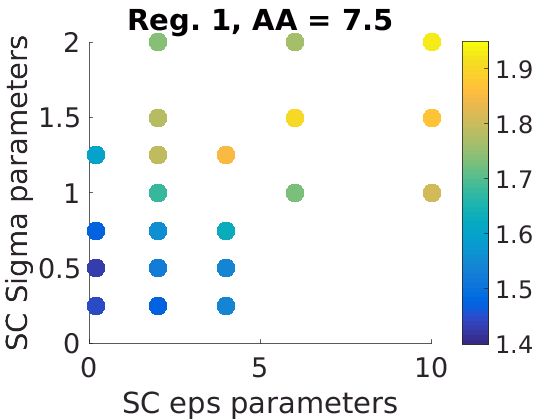


figure()
hold on

i02 = find((dims(:,1)==7.5) & (dims(:,6) ~=0));
i01 = find((dims(:,1)==7.5) & (dims(:,6) ==0));
scatter(dims(i01,2),dims(i01,3),200,dims(i01,4))
scatter(dims(i02,2),dims(i02,3),200,dims(i02,4),'filled')
colorbar
set(gca,'fontsize',20)
xlabel('SC eps parameters')
ylabel('SC Sigma parameters')
title('Reg. 1, AA = 7.5')
caxis([1.4 1.95])
savefig([saveloc '/dimr1A750'])
saveas(gcf,[saveloc '/dimr1A750'],'pdf')

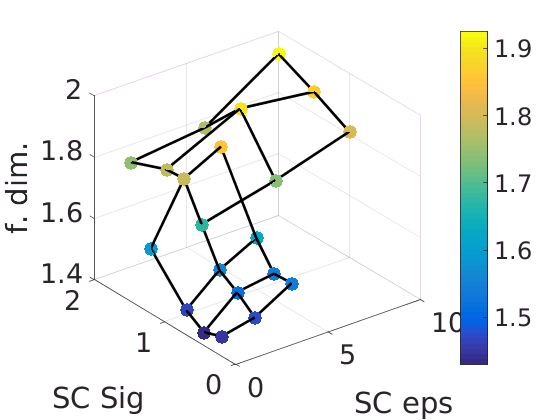



f = figure();
hold on

f = errorMesh(dims(i02,2),dims(i02,3),dims(i02,4),0.0*ones(size(dims(i02,2))),[0 0 0],f);
figure(f);
colorbar
set(gca,'fontsize',20);
xlabel('SC eps')
ylabel('SC Sig')
zlabel('f. dim.')
savefig([saveloc '/dimr1A7503D'])
saveas(gcf,[saveloc '/dimr1A7503D'],'pdf')

**Region 2**

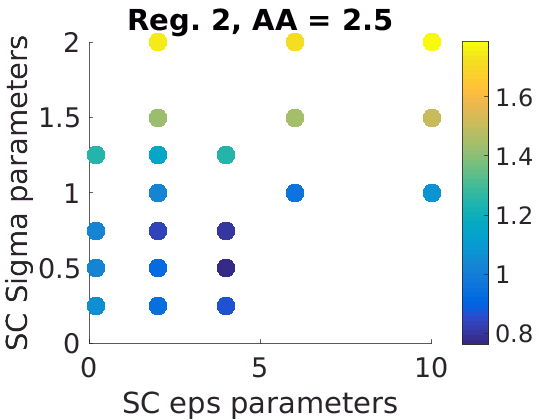

figure()
hold on

i02 = find((dims(:,1)==2.5) & (dims(:,6) ~=0));
i01 = find((dims(:,1)==2.5) & (dims(:,6) ==0));
scatter(dims(i01,2),dims(i01,3),200,dims(i01,5))
scatter(dims(i02,2),dims(i02,3),200,dims(i02,5),'filled')
colorbar
%caxis([0.75 2.1])
set(gca,'fontsize',20)
xlabel('SC eps parameters')
ylabel('SC Sigma parameters')
title('Reg. 2, AA = 2.5')
savefig([saveloc '/dimr2A250'])
saveas(gcf,[saveloc '/dimr2A250'],'pdf')

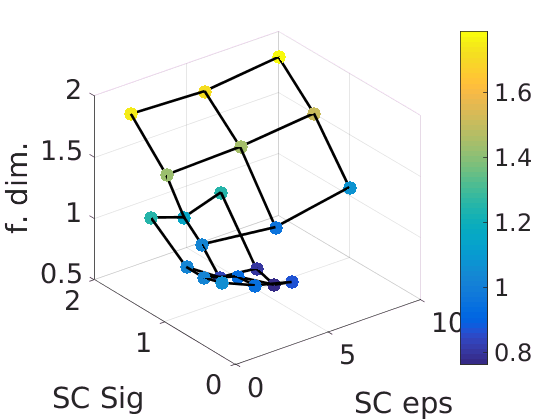


f = figure();
hold on

f = errorMesh(dims(i02,2),dims(i02,3),dims(i02,5),0.0*ones(size(dims(i02,2))),[0 0 0],f);
figure(f);
colorbar
set(gca,'fontsize',20);
xlabel('SC eps')
ylabel('SC Sig')
zlabel('f. dim.')
savefig([saveloc '/dimr2A2503D'])
saveas(gcf,[saveloc '/dimr2A2503D'],'pdf')

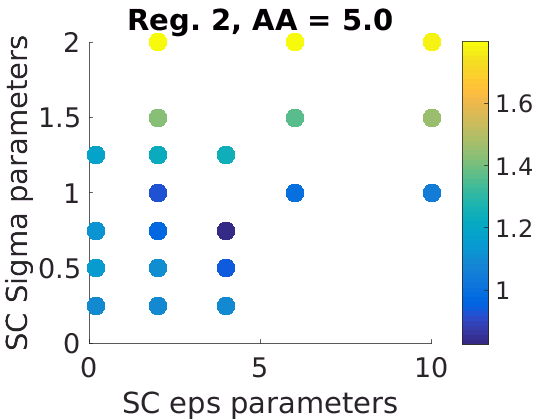


figure()
hold on

i02 = find((dims(:,1)==5) & (dims(:,6) ~=0));
i01 = find((dims(:,1)==5) & (dims(:,6) ==0));
scatter(dims(i01,2),dims(i01,3),200,dims(i01,5))
scatter(dims(i02,2),dims(i02,3),200,dims(i02,5),'filled')
colorbar
set(gca,'fontsize',20)
xlabel('SC eps parameters')
ylabel('SC Sigma parameters')
title('Reg. 2, AA = 5.0')
%caxis([0.75 2.1])
savefig([saveloc '/dimr2A500'])
saveas(gcf,[saveloc '/dimr2A500'],'pdf')

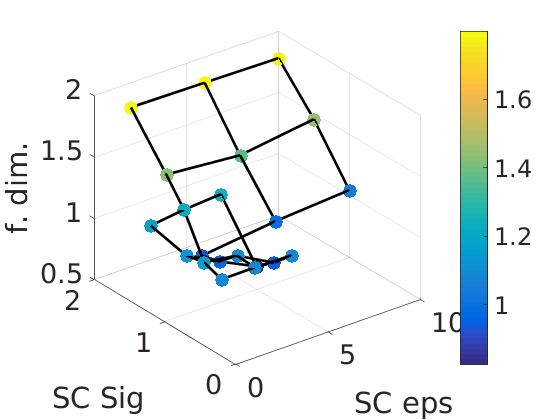


f = figure();
hold on

f = errorMesh(dims(i02,2),dims(i02,3),dims(i02,5),0.0*ones(size(dims(i02,2))),[0 0 0],f);
figure(f);
colorbar
set(gca,'fontsize',20);
xlabel('SC eps')
ylabel('SC Sig')
zlabel('f. dim.')
savefig([saveloc '/dimr2A5003D'])
saveas(gcf,[saveloc '/dimr2A5003D'],'pdf')

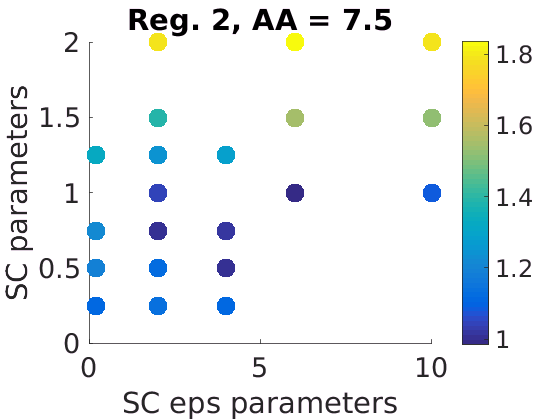


figure()
hold on

i02 = find((dims(:,1)==7.5) & (dims(:,6) ~=0));
i01 = find((dims(:,1)==7.5) & (dims(:,6) ==0));
scatter(dims(i01,2),dims(i01,3),200,dims(i01,5))
scatter(dims(i02,2),dims(i02,3),200,dims(i02,5),'filled')
colorbar
set(gca,'fontsize',20)
xlabel('SC eps parameters')
ylabel('SC parameters')
title('Reg. 2, AA = 7.5')
%caxis([0.75 2.1])
savefig([saveloc '/dimr2A750'])
saveas(gcf,[saveloc '/dimr2A750'],'pdf')

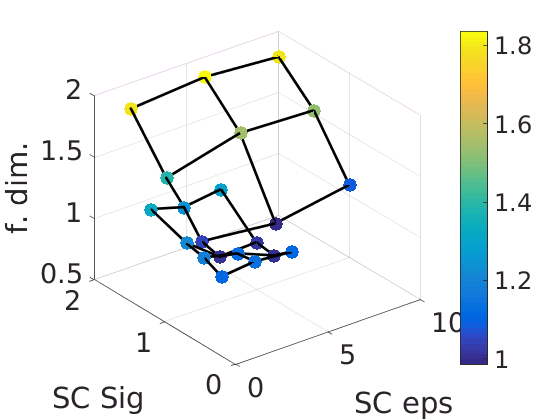


f = figure();
hold on

f = errorMesh(dims(i02,2),dims(i02,3),dims(i02,5),0.0*ones(size(dims(i02,2))),[0 0 0],f);
figure(f);
colorbar
set(gca,'fontsize',20);
xlabel('SC eps')
ylabel('SC Sig')
zlabel('f. dim.')
savefig([saveloc '/dimr2A7503D'])
saveas(gcf,[saveloc '/dimr2A7503D'],'pdf')

## Division between regions

mdiv = mean(exp(dims(:,6)));
smdiv = std(exp(dims(:,6)));
fprintf('The mean turnover between regions is: %f +/- %f nm',mdiv,smdiv)

The mean turnover between regions is: 5.065667 +/- 1.497210 nm

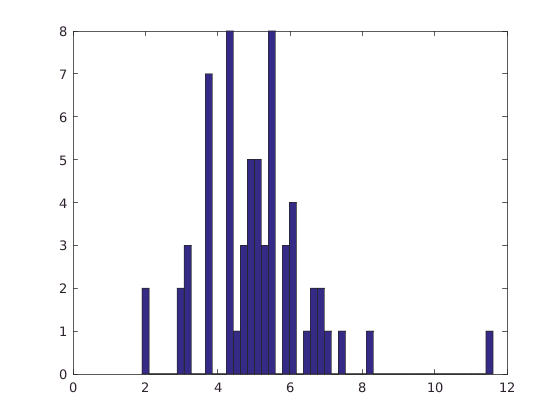

figure()
hist(exp(dims(:,6)),50)

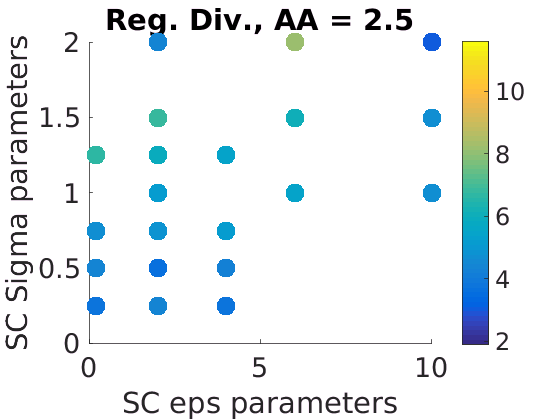

figure()
hold on
%colormap copper
i02 = find((dims(:,1)==2.5) & (dims(:,6) ~=0));
i01 = find((dims(:,1)==2.5) & (dims(:,6) ==0));
scatter(dims(i01,2),dims(i01,3),200,exp(dims(i01,6)))
scatter(dims(i02,2),dims(i02,3),200,exp(dims(i02,6)),'filled')
colorbar
caxis([min(exp(dims(:,6))) max(exp(dims(:,6)))])
set(gca,'fontsize',20)
xlabel('SC eps parameters')
ylabel('SC Sigma parameters')
title('Reg. Div., AA = 2.5')
savefig([saveloc '/dimrdivA250'])
saveas(gcf,[saveloc '/dimrdivA250'],'pdf')

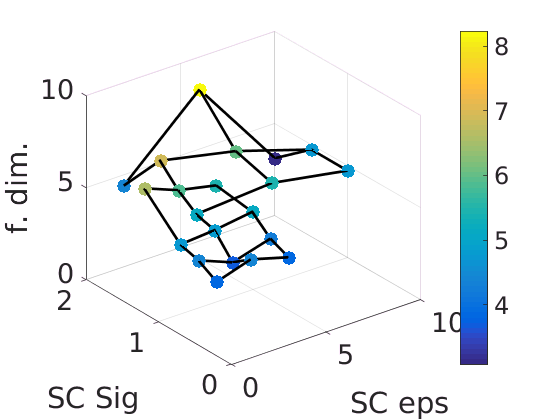


f = figure();
hold on

f = errorMesh(dims(i02,2),dims(i02,3),exp(dims(i02,6)),0.0*ones(size(dims(i02,2))),[0 0 0],f);
figure(f);
colorbar
set(gca,'fontsize',20);
xlabel('SC eps')
ylabel('SC Sig')
zlabel('f. dim.')
savefig([saveloc '/dimrdivA2503D'])
saveas(gcf,[saveloc '/dimrdivA2503D'],'pdf')

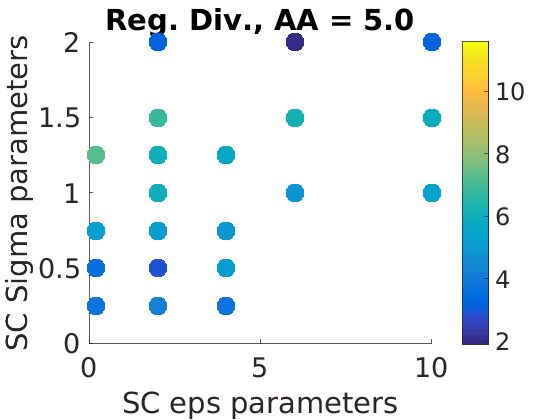


figure()
hold on
%colormap copper
i02 = find((dims(:,1)==5) & (dims(:,6) ~=0));
i01 = find((dims(:,1)==5) & (dims(:,6) ==0));
scatter(dims(i01,2),dims(i01,3),200,exp(dims(i01,6)))
scatter(dims(i02,2),dims(i02,3),200,exp(dims(i02,6)),'filled')
colorbar
set(gca,'fontsize',20)
xlabel('SC eps parameters')
ylabel('SC Sigma parameters')
title('Reg. Div., AA = 5.0')
caxis([min(exp(dims(:,6))) max(exp(dims(:,6)))])
savefig([saveloc '/dimrdivA500'])
saveas(gcf,[saveloc '/dimrdivA500'],'pdf')

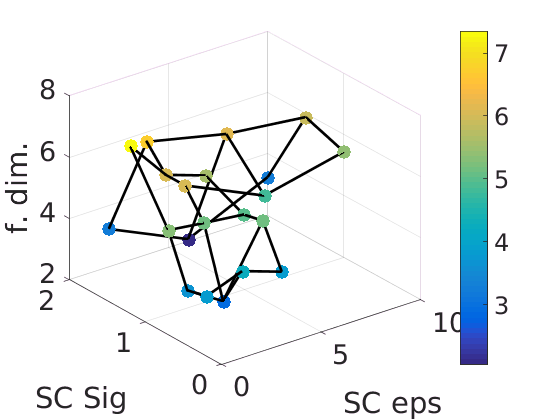


f = figure();
hold on

f = errorMesh(dims(i02,2),dims(i02,3),exp(dims(i02,6)),0.0*ones(size(dims(i02,2))),[0 0 0],f);
figure(f);
colorbar
set(gca,'fontsize',20);
xlabel('SC eps')
ylabel('SC Sig')
zlabel('f. dim.')
savefig([saveloc '/dimrdivA5003D'])
saveas(gcf,[saveloc '/dimrdivA5003D'],'pdf')

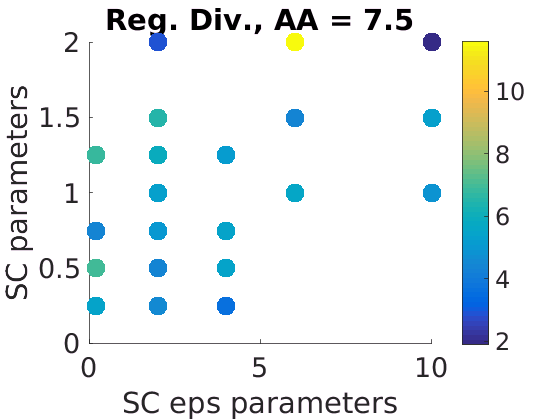


figure()
hold on
%colormap copper
i02 = find((dims(:,1)==7.5) & (dims(:,6) ~=0));
i01 = find((dims(:,1)==7.5) & (dims(:,6) ==0));
scatter(dims(i01,2),dims(i01,3),200,exp(dims(i01,6)))
scatter(dims(i02,2),dims(i02,3),200,exp(dims(i02,6)),'filled')
colorbar
set(gca,'fontsize',20)
xlabel('SC eps parameters')
ylabel('SC parameters')
title('Reg. Div., AA = 7.5')
caxis([min(exp(dims(:,6))) max(exp(dims(:,6)))])
savefig([saveloc '/dimrdivA750'])
saveas(gcf,[saveloc '/dimrdivA750'],'pdf')

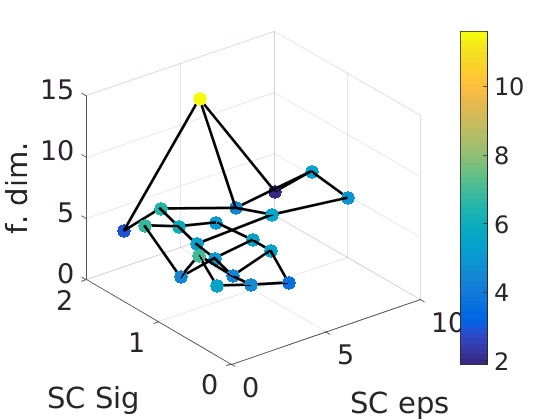


f = figure();
hold on

f = errorMesh(dims(i02,2),dims(i02,3),exp(dims(i02,6)),0.0*ones(size(dims(i02,2))),[0 0 0],f);
figure(f);
colorbar
set(gca,'fontsize',20);
xlabel('SC eps')
ylabel('SC Sig')
zlabel('f. dim.')
savefig([saveloc '/dimrdivA7503D'])
saveas(gcf,[saveloc '/dimrdivA7503D'],'pdf')